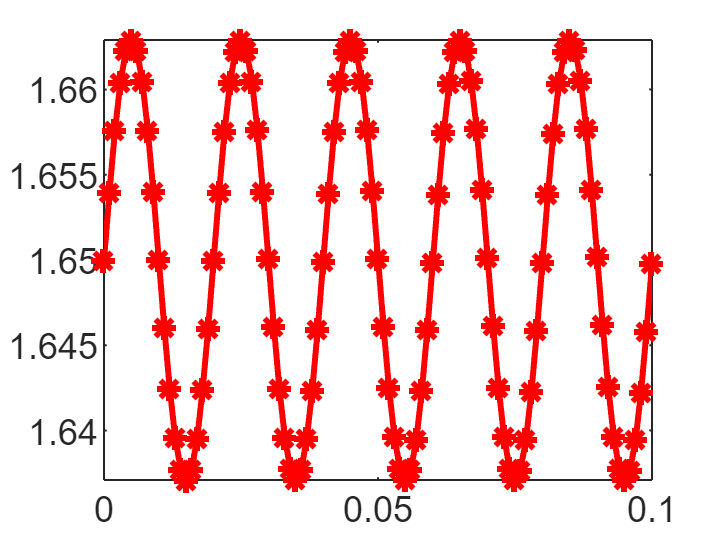

%Time Axis 
%Sampling Freq = 1KHz
%Max Time = 100ms
t = 0:0.001:0.1;
%Make a sine wave & clamp it to 1.65V
% it to 
s = 0.0129*sin(314*t)+1.65;
p = plot(t,s,'r*-');
p.LineWidth = 1.5;
hold on;

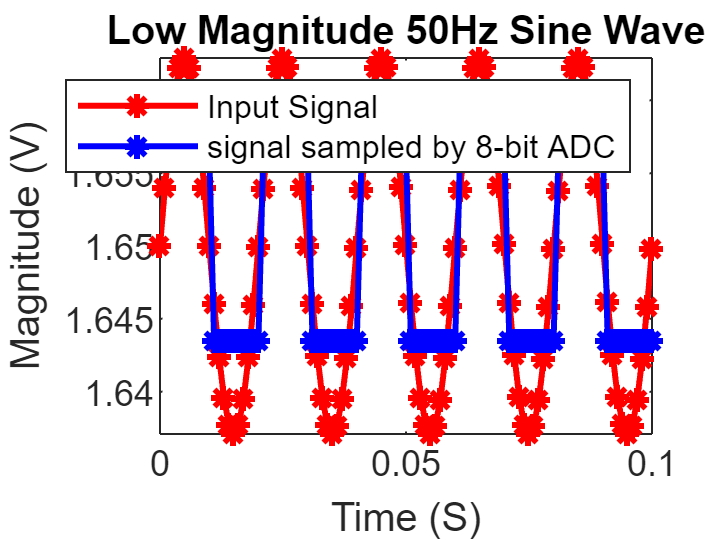

%Quantize the signal using the 8-bit resolution
%3.3V = Max (VRef)
s8 =s*255/3.3;
%Make s8 as 8 bit int
is8 = uint8(s8);
%Convert back to analog
as8 = double(is8)*3.3/255;
%Now plot the signal
p = plot(t,as8,'b*-');
p.LineWidth = 1.5;
title('Low Magnitude 50Hz Sine Wave');
xlabel('Time (S)');
ylabel('Magnitude (V)')
legend('Input Signal','signal sampled by 8-bit ADC');

%axis([0.04, 0.045, 1.6, 1.8]);

%Quantize the signal using the 8-bit resolution
%3.3V = Max (VRef)
s16 =s*65535/3.3;
%Make s8 as 8 bit int
is16 = uint16(s16);
%Convert back to analog
as16 = double(is16)*3.3/65535;
%Now plot the signal
plot(t,as16,'g*')
%axis([0.04, 0.045, 1.6, 1.8]);